% save("emg.mat","Xs","Emg","Emg_rms");
% save("acc.mat","Xs_acc","AccX","AccY","AccZ");

clear all;
close all;
clc;

load("acc.mat");
load("emg.mat");

% plot(Xs,emg_rms);
% hold on;

EMG spike detection


% plot( emg_a);
% spike=zeros(25,2);
spike_emg =zeros(25,1);
spike_idx = zeros(25,1);
threshold = 1.4e-05;

wind= 2000;
k=1;
% for i = 2001:(length(emg_a)-2000)
i = wind + 1;
while i<=(length(emg_rms)-wind) 
    if (max(emg_rms(i-wind:i)))<=threshold && min(emg_rms(i+10:i+100)>= threshold)
        spike_emg(k)= emg_rms(i-500);
        spike_idx(k) = Xs(i-500);
        i = i+2500;
        k = k+1;
    else 
        i = i+1;
    end
end
spike_emg = nonzeros(spike_emg);
spike_idx = nonzeros(spike_idx);

Plot EMG spike starting points

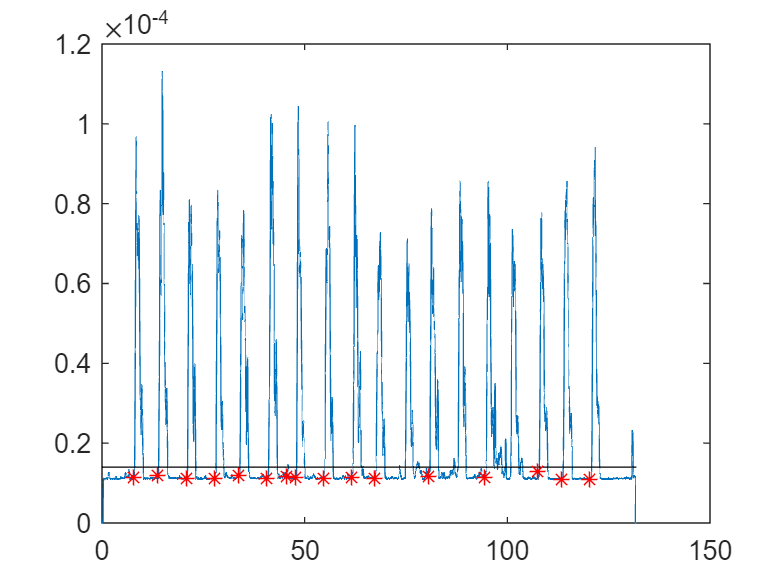

plot(Xs,emg_rms);
hold on;
line([0 Xs(end)], [threshold threshold], 'LineWidth', 0.5, 'Color', 'k');
plot(spike_idx,spike_emg,'r*');
hold off;

ACC spike data. 

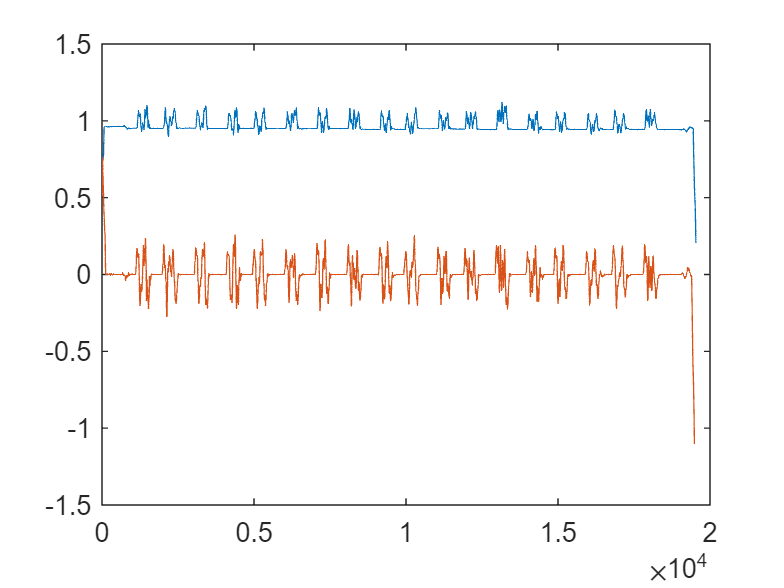

Acc = sqrt(ACCX.^2 + ACCY.^2 + ACCZ.^2);

Acc_rms = movmean(Acc,100);

Acc_diff = diff(Acc_rms);

Xs_acc_diff = diff(Xs_acc);

Acc_slope = Acc_diff./Xs_acc_diff;
Acc_slope(end+1) = NaN;


slope_rms = movmean(Acc_slope,100);

% plot(Xs_acc,Acc);
% hold on;
% plot(Acc_rms);
plot(Acc_rms);
hold on;
% plot(Xs_acc,Acc_slope);
plot(slope_rms);
hold off;

Ploting the ACC spike points. 

spike_acc =zeros(25,1);
acc_idx = zeros(25,1);
lower_th = 0.015;
upper_th = 0.05;

window= 100;
k=1;
% for i = 2001:(length(emg_a)-2000)
i = window + 1;
while i<=(length(slope_rms)-window) 
    if (max(slope_rms(i-window:i)))<=lower_th && min(slope_rms(i+5:i+25)>= lower_th)
        spike_acc(k)= Acc_rms(i-5);
        acc_idx(k) = Xs_acc(i-5);
        i = i+650;
        k = k+1;
    else 
        i = i+1;
    end
end
spike_acc = nonzeros(spike_acc);
acc_idx = nonzeros(acc_idx);

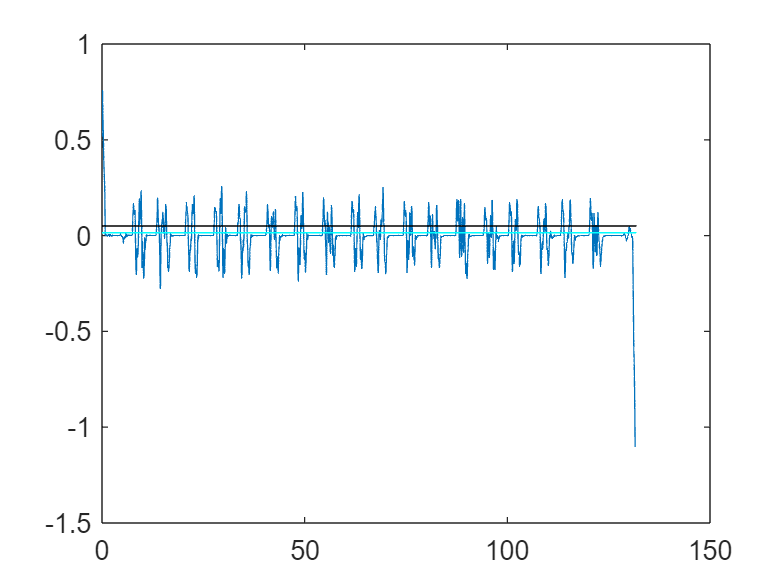

plot(Xs_acc,slope_rms);
hold on;
line([0 Xs_acc(end)], [upper_th upper_th], 'LineWidth', 0.5, 'Color', 'k');
line([0 Xs_acc(end)], [lower_th lower_th], 'LineWidth', 0.5, 'Color', 'c');
hold off;

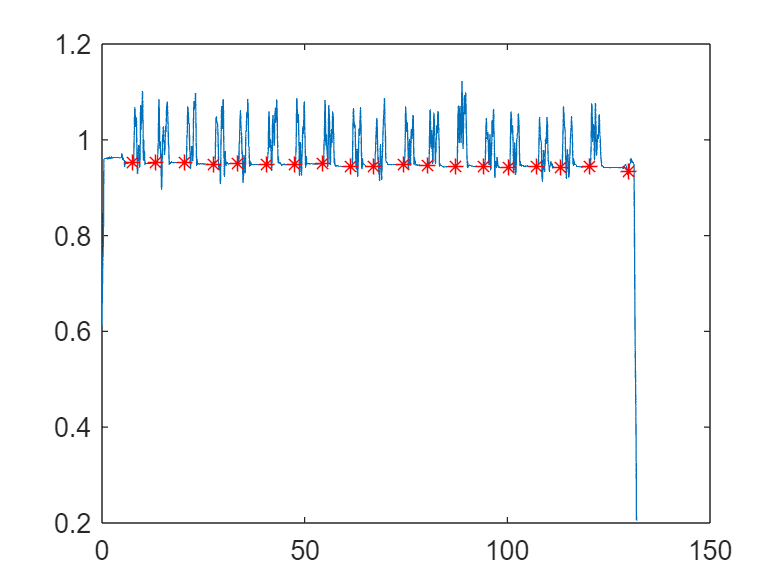

plot (Xs_acc,Acc_rms);
hold on;
plot(acc_idx,spike_acc,'r*');
hold off;